format long
N = 400; %Number of independent Bernoulli Trials
x = 0:400; % Number of Successes
p = 0.01;

lambda = N*p; %Probability of SUccess
y = binopdf(x, N, p); %Binomial PDF in-built funrion with parameter x and p
z = poisspdf(x, lambda); %Poisson PDF

### Plotting The Probability Against The Bernoulli Trials

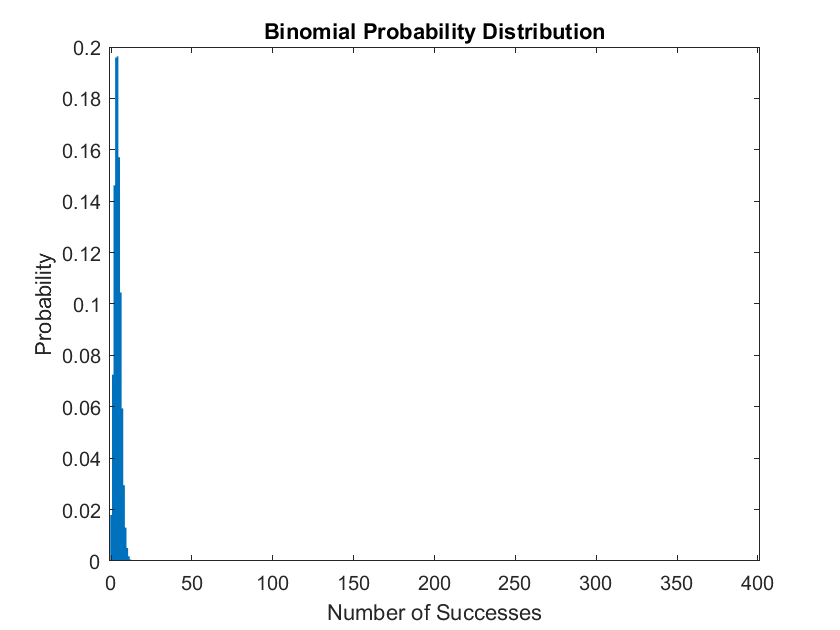

bar(x, y, 1) % Histogram of outputs
xlabel('Number of Successes')
ylabel('Probability')
title("Binomial Probability Distribution")

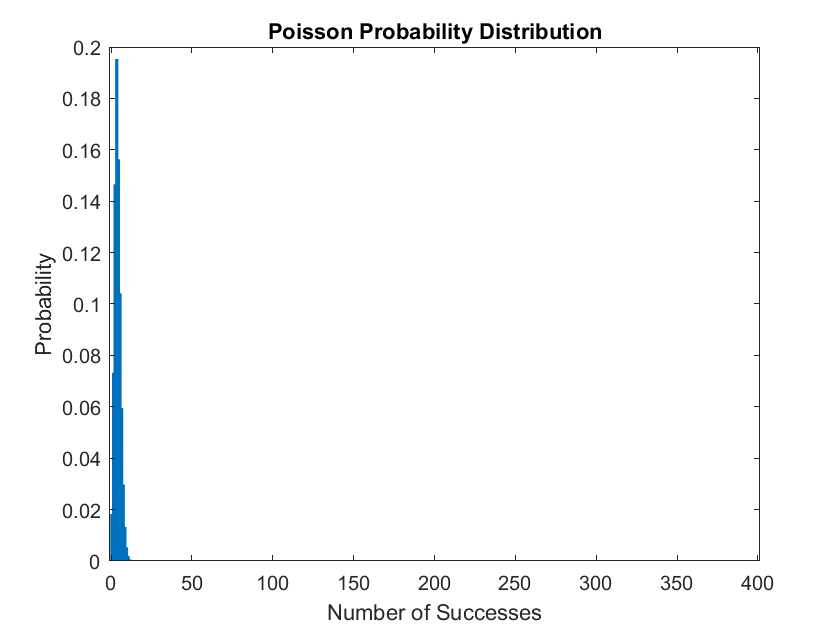

bar(x,z,1)
title("Poisson Probability Distribution")
xlabel('Number of Successes')
ylabel('Probability')

### Normality Test

mu = N*p;
sigma = sqrt(mu*(1-p));
x2 = 0:0.1:N

x2 = 	1.0e+02 *

                   0   0.001000000000000   0.002000000000000   0.003000000000000   0.004000000000000   0.005000000000000   0.006000000000000   0.007000000000000   0.008000000000000   0.009000000000000   0.010000000000000   0.011000000000000   0.012000000000000   0.013000000000000   0.014000000000000   0.015000000000000   0.016000000000000   0.017000000000000   0.018000000000000   0.019000000000000   0.020000000000000   0.021000000000000   0.022000000000000   0.023000000000000   0.024000000000000   0.025000000000000   0.026000000000000   0.027000000000000   0.028000000000000   0.029000000000000   0.030000000000000   0.031000000000000   0.032000000000000   0.033000000000000   0.034000000000000   0.035000000000000   0.036000000000000   0.037000000000000   0.038000000000000   0.039000000000000   0.040000000000000   0.041000000000000   0.042000000000000   0.043000000000000   0.044000000000000   0.045000000000000   0.046000000000000   0.047000000000000   0.048000000000000   

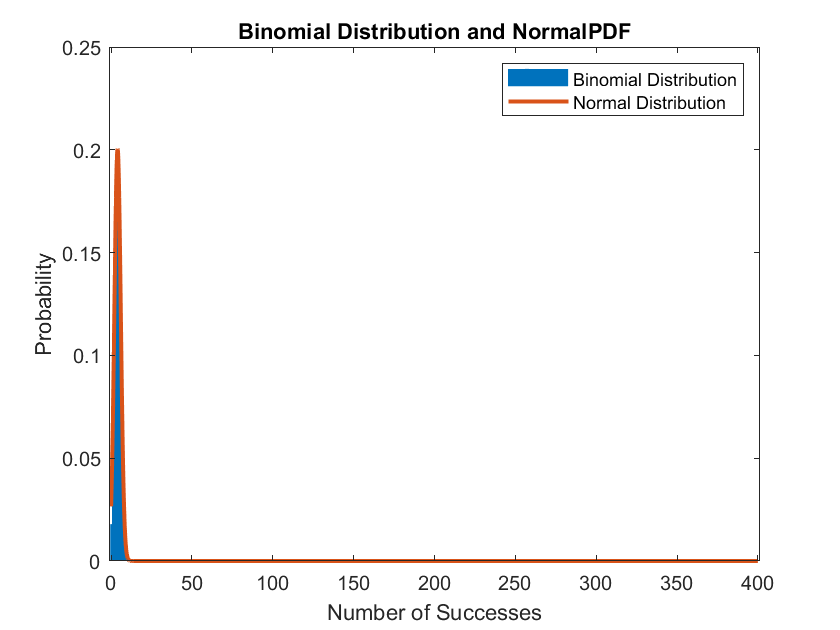

y2 = normpdf(x2, mu, sigma);
bar(x,y,1)
hold on
plot(x2, y2, 'LineWidth', 2)
xlabel('Number of Successes')
ylabel('Probability')
title('Binomial Distribution and NormalPDF')
legend('Binomial Distribution','Normal Distribution')
hold off